clear;close all; clc

**Lab # 1: Megan Miyasaki**

**Partner: Kuan Lee**

**Part 1: A little Statistics **

**Converting a probability into a 'sigma'.**

mu=0;
sigma=1;
x=-1:0.00001:1;
pd=pdf('Normal',x,mu,sigma);
plot(x,pd)

P = normcdf(1,mu,sigma)

P = 0.8413

x=norminv(P,mu,sigma)

x = 1

The code above shows that I used the standard normal distribution and integrated, to get the probabiltiy of what I set the zscore to be, as well as what the zscore should be given the probability. I chose the zscore of 1 out of simplicity, below is a table with the highlighted zscore and probability. 

 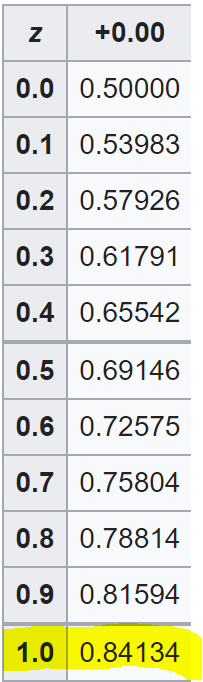

p2=0.2

p2 = 0.2000

x=norminv(p2,mu,sigma)

x = -0.8416

I chose 0.2 because when I integrate of negative infinity to positive infinity the mean or mu is 0.5, so by choosing a probablilty less than mu, I know that i will get a negative number. 

**Other continuous analytic distributions: Exponential **

clear all; close all; clc;

mu=1

mu = 1

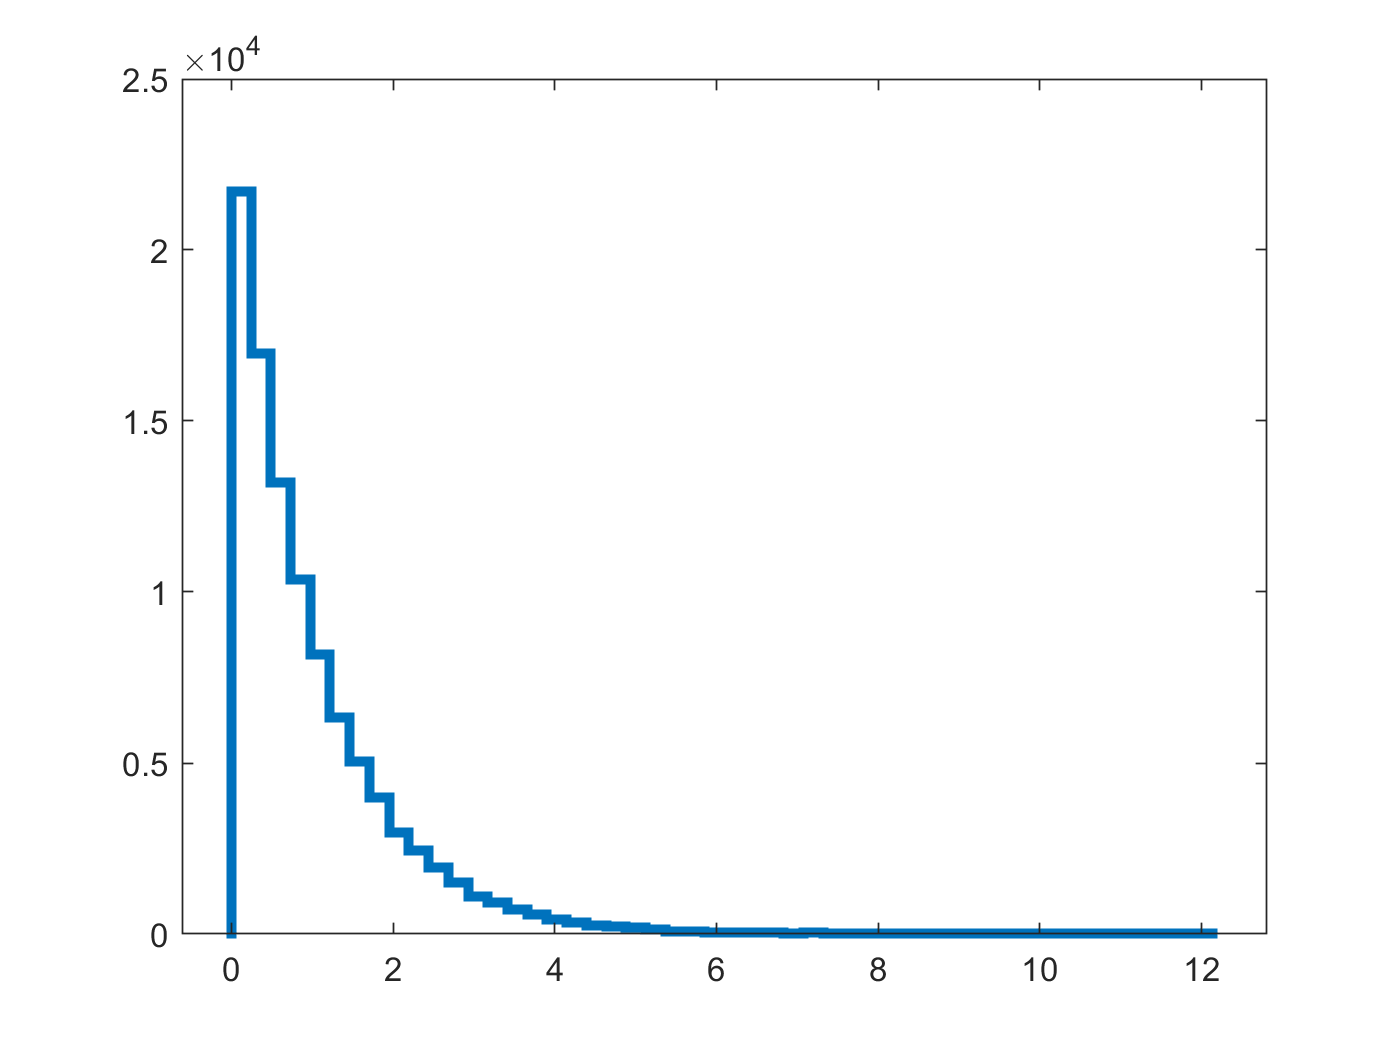

d = random('Exponential', mu, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)




histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on 
x = 0:0.001:10000;
pd=exppdf(x,mu);
plot(x,expcdf(pd,mu),"LineWidth",2);
set(gca,'XScale','log')


**Signal-free data:**

Imagine that your signal-free data follows the distribution you have chosen; and you have a measurement for which you need to determine the 'sigma'

**Select a value for your hypothetical measurement**

0.9714

**Clearly state the statistical question you want to ask in words**

How accurate is the exponential distribution, for the chosen measurment 0.9714, for the zscore that we will find. 

**Convert your word question into a mathematical integral**


$$f\left(x\right)=\int \lambda e^{-\lambda x} \mathrm{dx}$$



$$\mu =\sigma =\frac{1}{\lambda }$$



$$P\left(X>a+b|X>a\right)=P\left(X>b\right)$$


**Use the math to calculate the probability that the background produced the signal (Hint: you will want to use the statistics functions to do the integrals. **`cdf()`** and **`icdf()`** in MatLab; **`.cdf()`** and **`.ppf()`** in scipy). And Convert your probability into an equivalent 'sigma'**

clear;close all;clc;

mu=1;
x = 0:0.001:10000;
pd=exppdf(x,mu);


P = expcdf(pd,mu);
z=norminv(P,mu);

**Part 2: Non-continuous Distribution: Binomial Distribution **

In many physics contexts we are counting descrete events. We can detect 9 gamma-rays or 10 gamma-rays, but 9.2 gamma-rays makes no sense. In these contexts the continuous distributions make no sense and we instead must use discrete distributions. The two most common of these are the Binomial and the Poisson (which is a limiting case of the Binomial).

**Make a series of plots with different parameters; and explain the features. (Hint: your plots will need to be discrete, sometimes 'stairs' style plots can be helpful).**

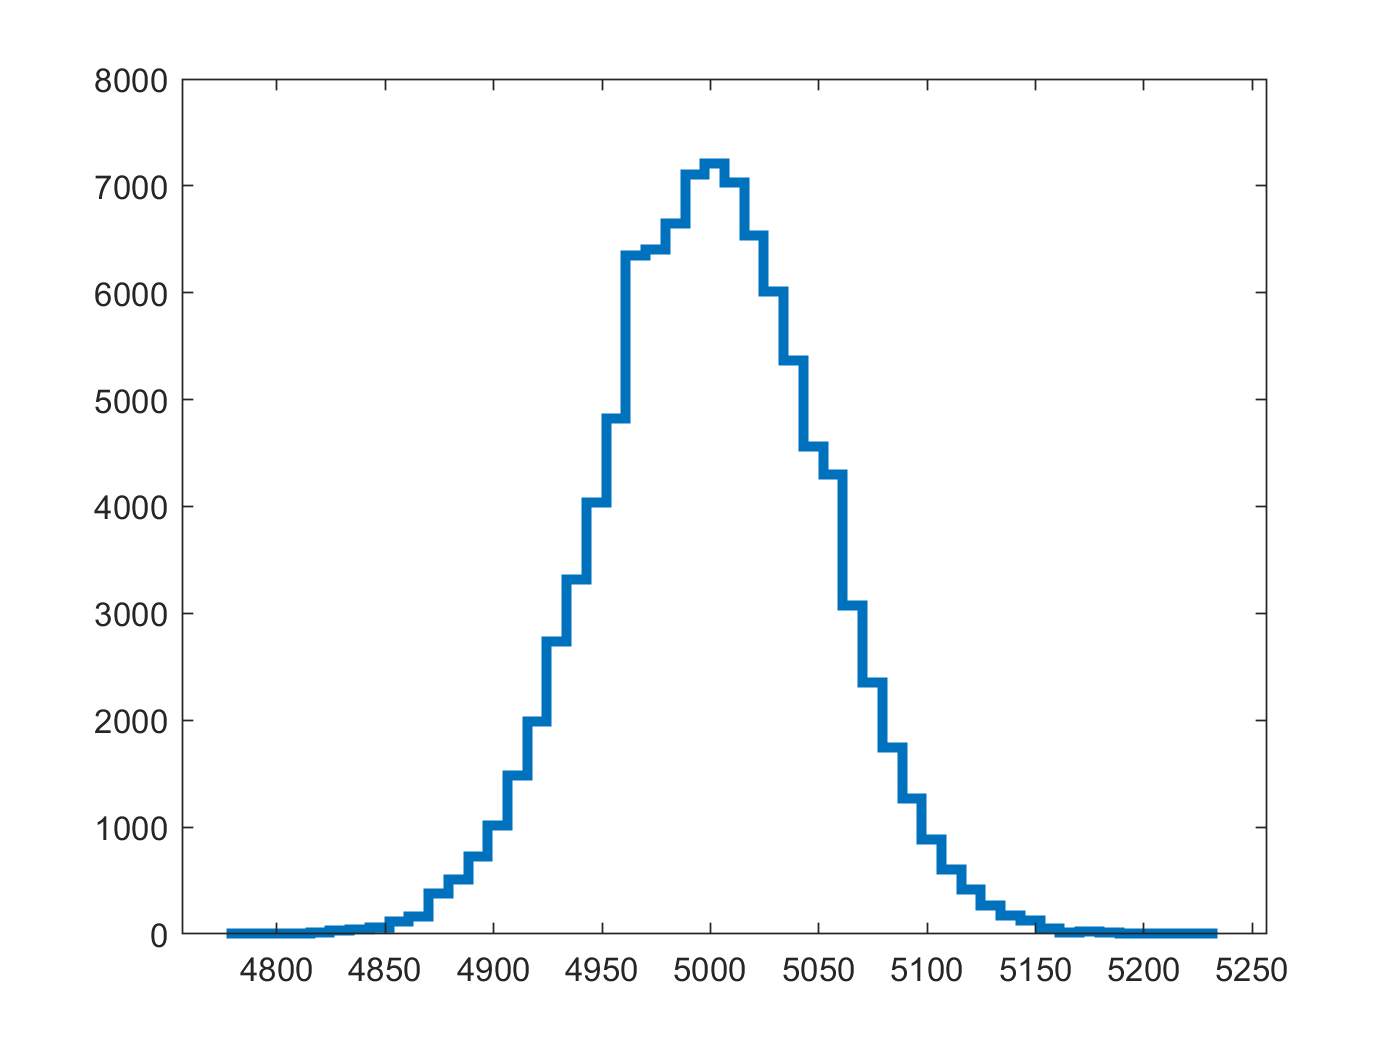

clear all; close all; clc;

N=10000;
P = 0.5;
d = random('Binomial', N,P,[1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)

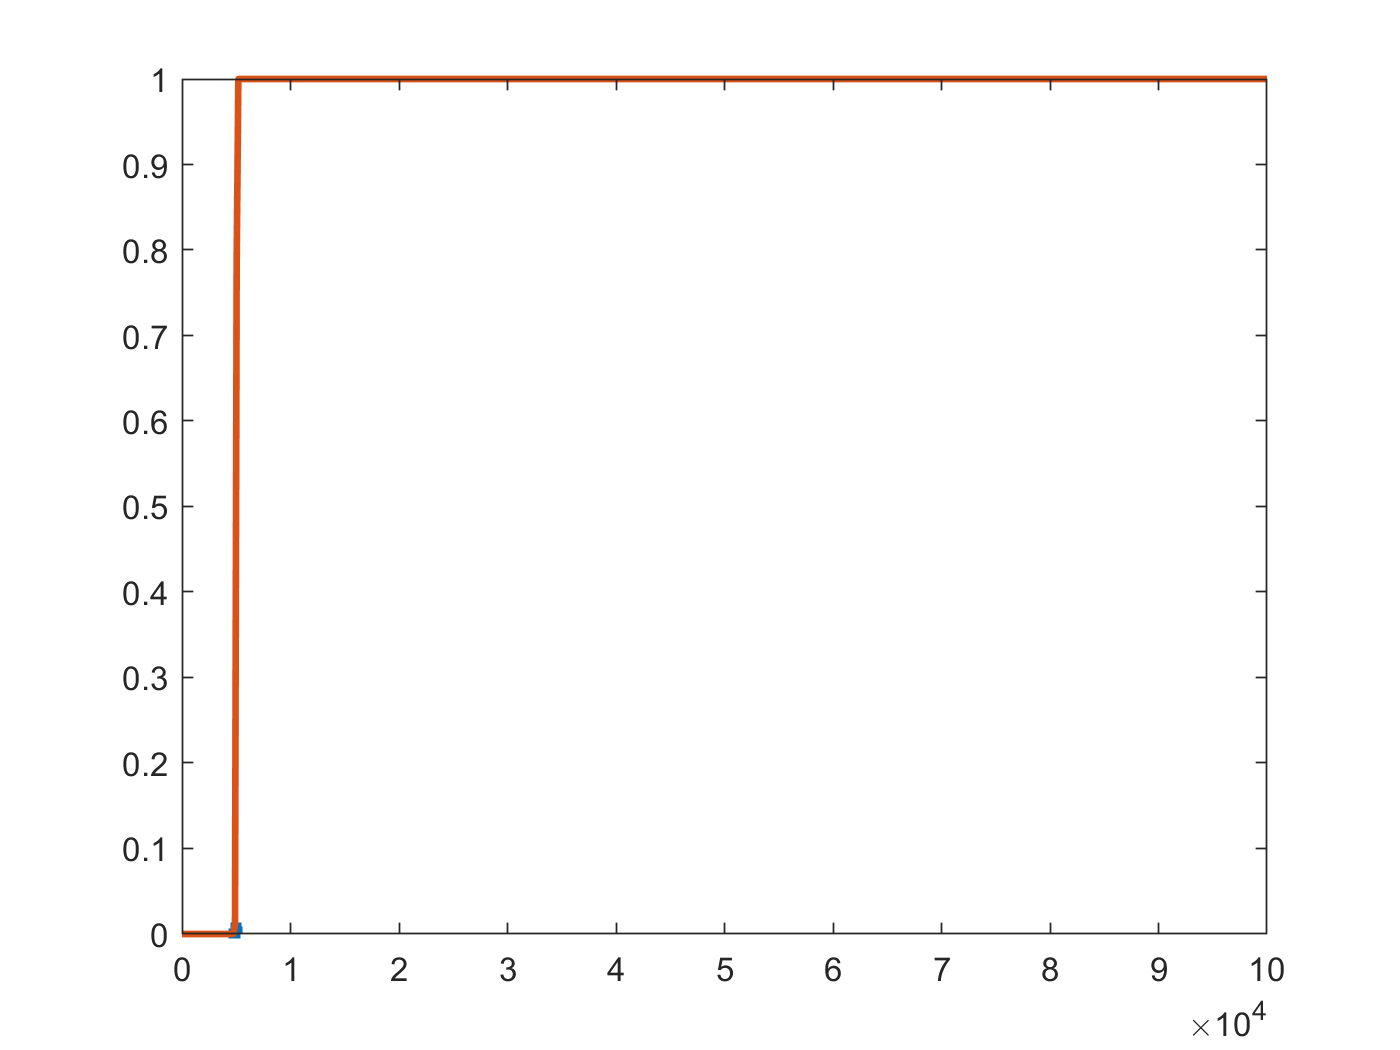




histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on 
x = 1:100000;
pd=binopdf(x,N,P);
plot(x,binocdf(x,N,P),"LineWidth",2);

%if you know how to fix my plot pls help, if not im honelsty just gonna
%leave it like this cause i cannot figure it out. 

**Again define a hypothetical question (clearly stated), and calculate the corresponding probability**

Even with a non-continuous distributions, can we detect 9 gamma rays, or 10 gamma rays, even 9.2, and what is the probablity that we calculated it correctly using our format. 

**Because the distributions are discrete, so are the probabilities and 'sigmas'. Think about this and discuss the implications for experiments. While the results are discrete, the parameters of the distributions are not. For example, the mean of a Poisson distribution can be 9.2. Think about and explain why this makes sense and what changes continuously and what doesn't.**

This is possible because we are using a discrete plots, since the parameters are continuous and only the distribution function is descrete we are allowed to look at this in a continuous manner. 